## Find relevant files

close all;

RatName = 'Claire';

CheckPosFile = dir('*position*.txt');
if ~isempty(CheckPosFile) && length(CheckPosFile.name)==1
    iPosFile = CheckPosFile.name;
end;

CheckStimFile = dir('*Stim*.txt');
if ~isempty(CheckStimFile) && length(CheckStimFile.name)==1
    iStimFile = CheckStimFile.name;
end;

CheckVidFile = dir('Claire*.avi');
if ~isempty(CheckVidFile) && length(CheckVidFile.name)==1
    iVidFile = CheckVidFile.name;
end;


iPosFile               =        'Claire_position2022-01-24T14_37_23.txt';
iStimFile             =        'Claire_Stim2022-01-24T14_37_37.txt';
iVidFile               =	   'Claire2022-01-24T14_37_23.avi';

sprintf(['Position file is %s,\nOpto-stim file is %s,\n' ...
    'VideoFile is %s \n'], iPosFile, iStimFile, iVidFile)

ans =     'Position file is Claire_position2022-01-24T14_37_23.txt,
     Opto-stim file is Claire_Stim2022-01-24T14_37_37.txt,
     VideoFile is Claire2022-01-24T14_37_23.avi 
     '

## Select clusters to get the correct trigger events

This will generate PosData in the workspace and the current directory

*All black ‘+’ are body position found in each frame. *

*All cyan ones are those that are sent to Bpod computer*

*The computer asks you to select and group these triggering events. Here, we choose some of them as cluster#1 and some as cluster#2. These definition will enter subsequent analysis. *

***An Excel table (DLCPos.xlsx) is also generated. ***

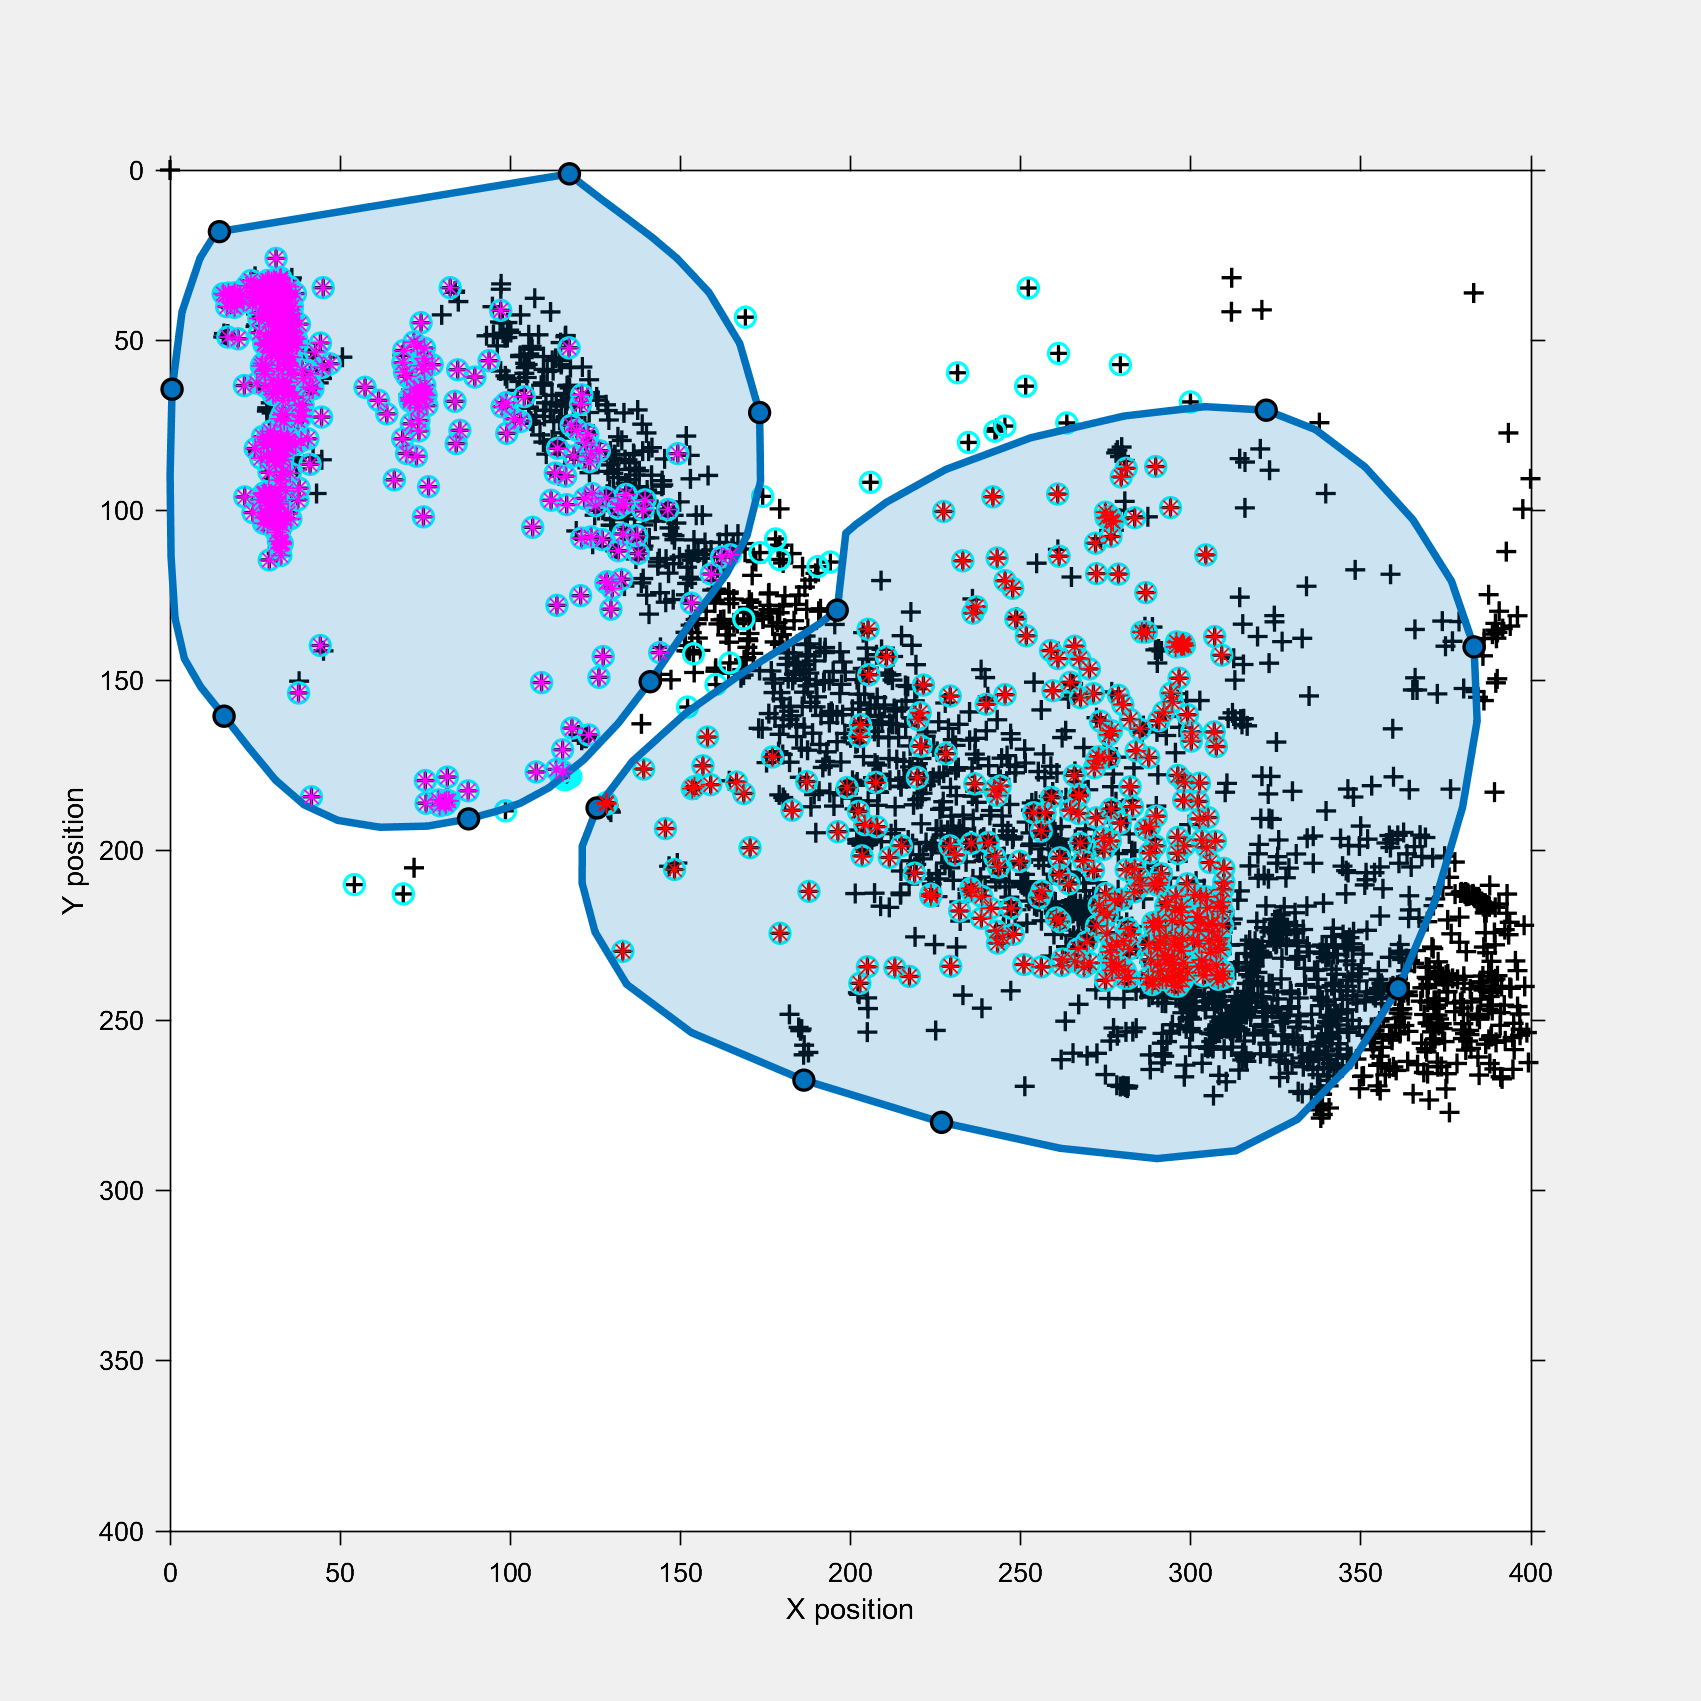

% Extract position data
PosData = ExtractPosData(iPosFile, iStimFile); % PosData includes frame index that produces stim signals.

## Extract stim frames from selected PosData

This will extract triggered frames for manual curation next

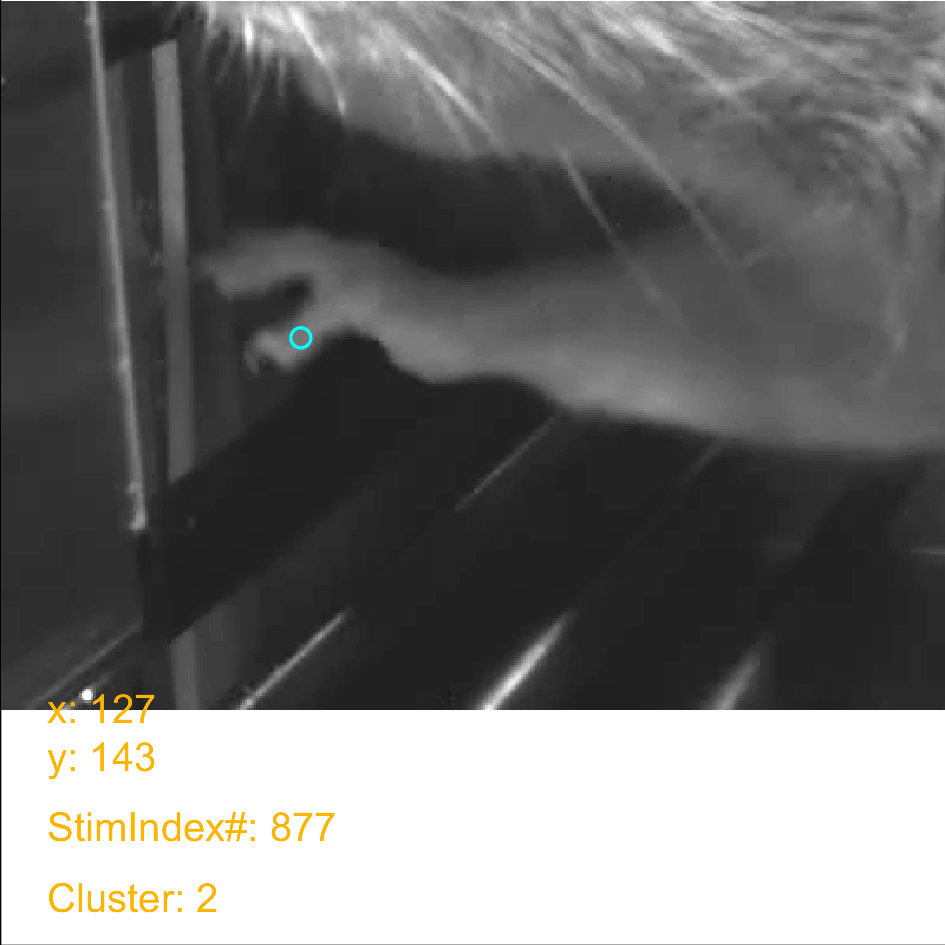

ans = 'Triggered frams are stored in DLCTriggerFrames_Claire2022-01-24T14_37_23.avi'


StimFrames = ExtractStimFrames(iVidFile, PosData);

whos

  Name                 Size                     Bytes  Class     Attributes

  CheckPosFile         1x1                       1227  struct              
  CheckStimFile        1x1                       1219  struct              
  CheckVidFile         1x1                       1209  struct              
  PosData              1x1                    5773978  struct              
  StimFrames         300x500x877            131550000  uint8               
  ans                  0x0                          0  double              
  iPosFile             1x38                        76  char                
  iStimFile            1x34                        68  char                
  iVidFile             1x29                        58  char                

